# Figure 4B, S5C, S5D

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';


load([dataDir filesep 'F041_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'NR75 DMSO DMSO'     }    {[1 2 3 4]}    {[ 2]}    {[1]}    {[0 0 0]}
    {'NR75 DMSO TAK'      }    {[1 2 3 4]}    {[ 3]}    {[1]}    {[0 0 0]}
    {'NR75 DMSO RO'       }    {[1 2 3 4]}    {[ 4]}    {[1]}    {[0 0 0]}
    {'NR75 DMSO TAK/RO'   }    {[1 2 3 4]}    {[ 5]}    {[1]}    {[0 0 0]}
    {'NR75 DMSO TAK/RO/2i'}    {[1 2 3 4]}    {[ 6]}    {[1]}    {[0 0 0]}
    {'NR75 DOX DMSO'      }    {[1 2 3 4]}    {[ 7]}    {[1]}    {[0 0 0]}
    {'NR75 DOX TAK'       }    {[1 2 3 4]}    {[ 8]}    {[1]}    {[0 0 0]}
    {'NR75 DOX RO'        }    {[1 2 3 4]}    {[ 9]}    {[1]}    {[0 0 0]}
    {'NR75 DOX TAK/RO'    }    {[1 2 3 4]}    {[10]}    {[1]}    {[0 0 0]}
    {'NR75 DOX TAK/RO/2i' }    {[1 2 3 4]}    {[11]}    {[1]}    {[0 0 0]}
    {'NR77 DMSO DMSO'     }    {[5 6 7 8]}    {[ 2]}    {[1]}    {[0 0 0]}
    {'NR77 DMSO TAK'      }    {[5 6 7 8]}    {[ 3]}    {[1]}    {[0 0 0]}
    {'NR77 DMSO RO'       }    {[5 6 7 8]}    {[ 4]}    {[1]}    {[0 0 


framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
   
    S(i).POI_realtime = S(i).POI/framesPerHr;
    
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

4B

conds=[11 16 12 17];
colors = [.5 .5 .5; .9 .2 .5; .6 .9 .2;.9 .4 .2;.1 .4 1;.3 1 .5; .8 .2 1;.8 .4 .2;.3 1 .5];
linetype = {'-','-','--','--'};
timeGate = [0 5];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 202

ans = 239

ans = 135

ans = 140

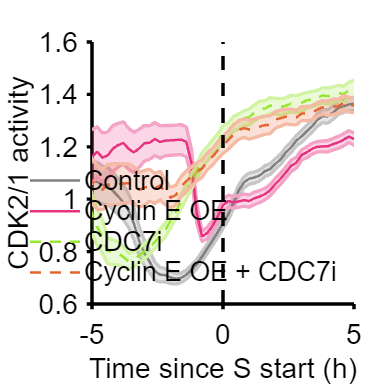


ylabel({'CDK2/1 activity'});xlabel('Time since S start (h)');
legend('Control','Cyclin E OE','CDC7i','Cyclin E OE + CDC7i','box','off','Location','southeast','fontsize',16);
set(gca,'linewidth',2,'fontsize',17)
xlim([-5 5]); 
ylim([.6 1.6]);
vline([0],'k--')

 % print_pdf(['fig_4B.pdf'])


S5C

conds=[11 16 12 17];
colors = [.1 .4 1; .9 .2 .5; .6 .9 .2;.9 .4 .2;.1 .4 1;.3 1 .5; .8 .2 1;.8 .4 .2;.3 1 .5];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 5];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
      inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 2000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 202

ans = 239

ans = 135

ans = 140

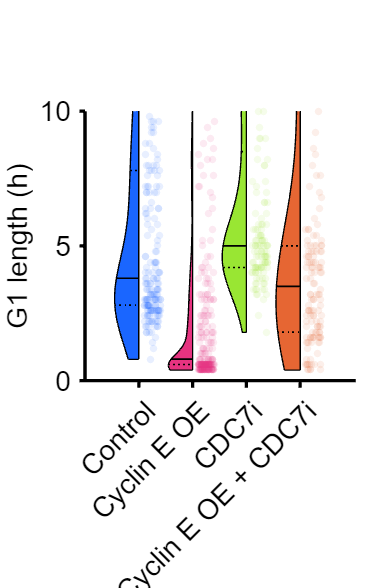


figure('Units', 'Inches', 'Position', [0, 0, 4, 6])

h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


xticklabels({'Control','Cyclin E OE','CDC7i','Cyclin E OE + CDC7i'})
ylim([0 10])
 xtickangle(45)
axis square
set(gca,'linewidth',2,'fontsize',17)



p=mediantest(ally(groups==1),ally(groups==2))

p = 6.4763e-26

p=mediantest(ally(groups==3),ally(groups==4))

p = 3.5781e-06

% print_pdf(['fig_S5C.pdf'])

S5D

conds=[11 16 12 17];
colors = [.5 .5 .5; .9 .2 .5; .6 .9 .2;.9 .4 .2;.1 .4 1;.3 1 .5; .8 .2 1;.8 .4 .2;.3 1 .5];
linetype = {'-','-','--','--'}
timeGate = [0 5];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 202

ans = 239

ans = 135

ans = 140

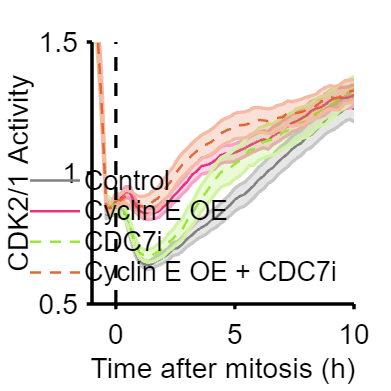


ylabel({'CDK2/1 Activity'});xlabel('Time after mitosis (h)');
legend('Control','Cyclin E OE','CDC7i','Cyclin E OE + CDC7i','box','off','Location','southeast','fontsize',16);
set(gca,'linewidth',2,'fontsize',17)
xlim([-1 10]); 
ylim([.5 1.5]);
vline([0],'k--')

 % print_pdf(['fig_S5D.pdf'])